# Problemas de valor inicial

## Sistema de dos ecuaciones lineales de primer orden

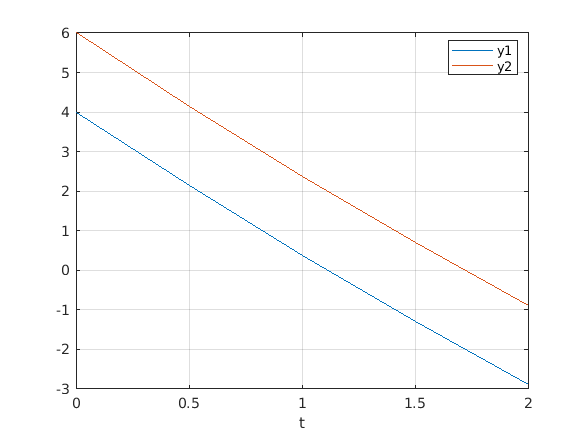

% y1' = -0.5*y1                 y1(0) = 4
% y2' = 4 - 0.3*y2 - 0.1*y1     y2(0) = 6

f = @(t,y) [-0.5*y(1) - 4 + 0.3*y(2) + 0.1*y(1)];
y0 = [4;6];
[t,y] = RK4(f, y0, 0, 2, 0.5);
plot(t,y);
xlabel('t');
legend('y1', 'y2','location', 'best');
grid on;

[t,y] = odeABM4(f, y0, 0, 2, 0.5);
plot(t,y);
xlabel('t');
legend('y1', 'y2','location', 'best');
grid on;

## Sistema de dos ecuaciones lineales **homogeneas** de primer orden

### Matriz M de coeficientes (constantes)

#### Sistema 1

% y' = 3*y-2*z     y(0)=1
% z' = 2*y-2*z     z(0)=-1
M = [ 3, -2; 2, -2]

M =      3    -2
     2    -2


b = [0;0];
fM = @(t,y) M*y + b;
y0 = [1;-1];
[t,y] = odeRK4(fM, y0, 0, 2, 0.5)

t =          0    0.5000    1.0000    1.5000    2.0000


y =     1.0000    4.8099   14.3020   39.5082  107.4709
   -1.0000    1.4948    6.5987   19.4190   53.5321


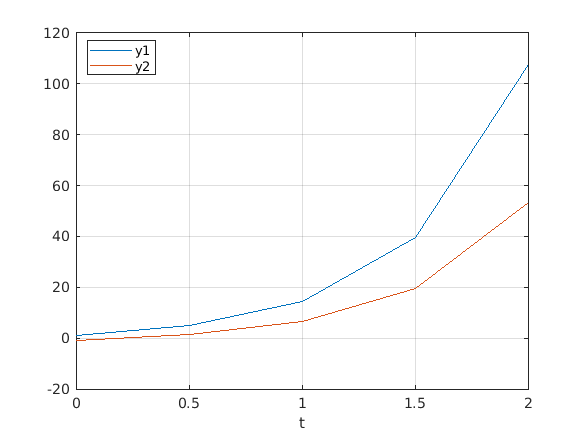

plot(t,y);
xlabel('t');
legend('y1', 'y2','location', 'best');
grid on;

[t,y] = odeRK45(fM, y0, 0, 2, 0.5)

t =          0    0.0010    0.0020    0.0029    0.0039    0.0049    0.0059    0.0068    0.0078    0.0088    0.0098    0.0107    0.0117    0.0127    0.0137    0.0146    0.0156    0.0166    0.0176    0.0186    0.0195    0.0205    0.0215    0.0225    0.0234    0.0244    0.0254    0.0264    0.0273    0.0283    0.0293    0.0303    0.0312    0.0322    0.0332    0.0342    0.0352    0.0361    0.0371    0.0381    0.0391    0.0400    0.0410    0.0420    0.0430    0.0439    0.0449    0.0459    0.0469    0.0479


y =     1.0000    1.0049    1.0098    1.0147    1.0196    1.0245    1.0294    1.0343    1.0393    1.0442    1.0492    1.0541    1.0591    1.0640    1.0690    1.0740    1.0790    1.0840    1.0890    1.0940    1.0990    1.1040    1.1091    1.1141    1.1191    1.1242    1.1293    1.1343    1.1394    1.1445    1.1496    1.1547    1.1598    1.1649    1.1700    1.1751    1.1802    1.1854    1.1905    1.1957    1.2008    1.2060    1.2112    1.2163    1.2215    1.2267    1.2319    1.2371    1.2424    1.2476
   -1.0000   -0.9961   -0.9922   -0.9883   -0.9844   -0.9804   -0.9765   -0.9726   -0.9687   -0.9648   -0.9608   -0.9569   -0.9530   -0.9491   -0.9451   -0.9412   -0.9372   -0.9333   -0.9294   -0.9254   -0.9215   -0.9175   -0.9136   -0.9096   -0.9057   -0.9017   -0.8978   -0.8938   -0.8898   -0.8859   -0.8819   -0.8779   -0.8740   -0.8700   -0.8660   -0.8620   -0.8581   -0.8541   -0.8501   -0.8461   -0.8421   -0.8381   -0.8341   -0.8301   -0.8261   -0.8221   -0.8181   -0.8141   -0.8101   -0

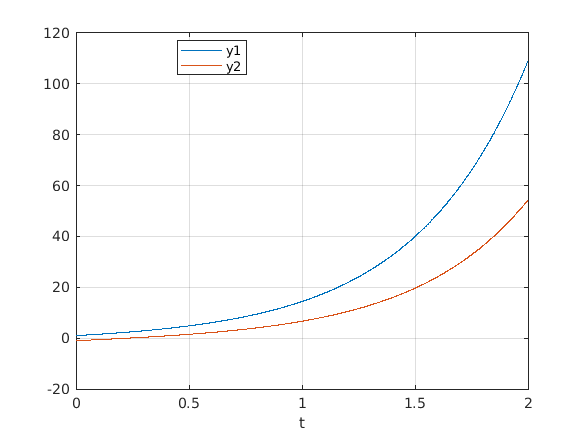

plot(t,y);
xlabel('t');
legend('y1', 'y2','location', 'best');
grid on;

[t,y] = odeEulerImplicito(fM, y0, 0, 2, 0.5)

Unable to perform assignment because the size of the left side is 1-by-1 and the size of the right side is 2-by-1.

Error in odeEulerImplicito (line 7)
    y(:,1) = y0;

plot(t,y);
xlabel('t');
legend('y1', 'y2','location', 'best');
grid on;

#### Sistema 2

% y' =  y+z     y(0)=0.1
% z' = -y+z     z(0)=0.2
M = [ 1, 1; -1, 1]

M =      1     1
    -1     1


b = [0;0];
fM = @(t,y) M*y + b;
y0 = [0.1;0.2];
[t,y] = RK4(fM, y0, 0, 2, 0.5)

t =          0    0.5000    1.0000    1.5000    2.0000


y =     0.1000    0.3031    0.6055    0.9279    1.0382
    0.2000    0.2104    0.0647   -0.3857   -1.2930


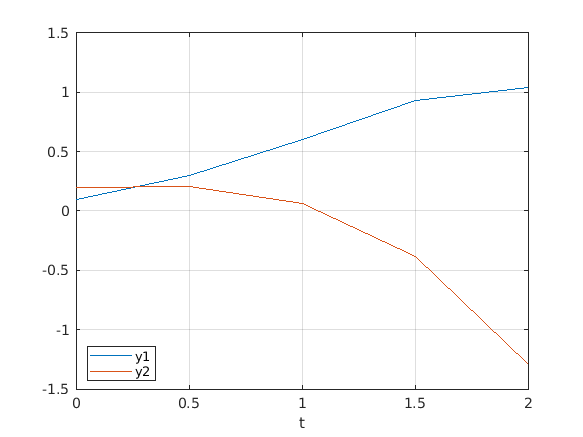

plot(t,y);
xlabel('t');
legend('y1', 'y2','location', 'best');
grid on;

#### Sistema 3

% y' = -y-6*z    y(0)=0
% z' = 3y+5*z    z(0)=2
M = [ -1, -6; 3, 5]
b = [0;0];
fM = @(t,y) M*y + b;
y0 = [1;-1];
[t,y] = RK4(fM, y0, 0, 2, 0.5)
plot(t,y);
xlabel('t');
legend('y1', 'y2','location', 'best');
grid on;

#### Sistema 4

% y' = -2*y + 5*exp(-t)
% z' = -(y*z^2)/2;

f = @(t,y) [-2*y(1) +5*exp(-t) + ((y(1)*y(2)^2)/2)];
y0 = [0;0];
[t,y] = RK4(f, y0, 0, 2, 0.5);
plot(t,y);
xlabel('t');
legend('y1', 'y2','location', 'best');
grid on;

#### Sistema 5

Pb 25.26 Chapra

Suponga que un proyectil se lanza hacia arriba desde la superficie de la Tierra. Se acepta que la única fuerza que actúa sobre el objeto es la fuerza de la gravedad, hacia abajo. En estas condiciones, se usa un balance de fuerza para obtener,


$$v^{\prime } =-g\frac{R^2 }{{\left(R+y\right)}^2 }$$


donde v = velocidad hacia arriba (m/s), t = tiempo (s), y = altitud (m) medida hacia arriba a partir de la superficie terrestre, g =aceleración gravitacional a la superficie terrestre (≈9.81 m/$s^2$), y R = radio de la tierra (≈6.37 × ${10}^6$ m). Determine la altura máxima que se obtendría si v(t = 0) = 1 400 m/s.

Sistema 5


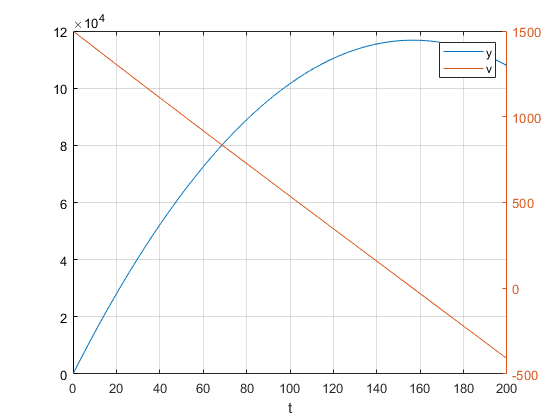

Ymax = 1.1678e+05

Imax = 1568

tMax = 156.7000

f = @(t,y) [-9.81*((63.37*10^6)^2)/(6.37*10^6 + y)^2];

y0 = 1400;
[t,y] = RK4(f, y0, 0, 2, 0.5);
plot(t,y);
xlabel('t');
legend('y1', 'y2','location', 'best');
grid on;

## Ecuación diferencial lineal homogenea de segundo orden

Con coeficientes constantes


$$y^{\textrm{''}} +ay^{\prime } +\textrm{by}=0$$


Se convierte a un sistema de dos ecuaciones diferenciales de primer orden definiendo una nueva variable $z=y^{\prime }$


$$\begin{array}{l}
y^{\prime } =z\\
z^{\prime } =y^{\textrm{''}} =-a\;z-b\;y
\end{array}$$



$${\left\lbrack \begin{array}{c}
y\\
z
\end{array}\right\rbrack }^{\prime } =\left\lbrack \begin{array}{cc}
0 & 1\\
-b & -a
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
y\\
z
\end{array}\right\rbrack$$


#### Segundo orden 1

$y^{\prime \prime } +y^{\prime } -2y=0$         $y\left(0\right)=3$, $y^{\prime } \left(0\right)=0$

% 

#### Segundo orden 2

$y^{\prime \prime } -y^{\prime } -2y=0$         $y\left(0\right)=0\ldotp 1$, $y^{\prime } \left(0\right)=0\ldotp 2$

%

#### Segundo orden 3

$y^{\prime \prime } +y^{\prime } -6y=0$         $y\left(0\right)=5$, $y^{\prime } \left(0\right)=0$

% 

#### Segundo orden 4

Harmonic oscillator

$y^{\prime \prime } +y=0$         $y\left(0\right)=4$, $y^{\prime } \left(0\right)=0$

%

#### Segundo orden 5

Motion of a mass connected to a spring, with viscous friction on the surface and an applied external force.

${3y}^{\prime \prime } +{18y}^{\prime } +102y=10$         $y\left(0\right)=0$, $y^{\prime } \left(0\right)=0$

%

#### Segundo orden 6

Resuelve el problema siguiente de t=0 a 5.

$y^{\prime \prime } +{0\ldotp 6y}^{\prime } +8y=0$         $y\left(0\right)=4$, $y^{\prime } \left(0\right)=0$

% 